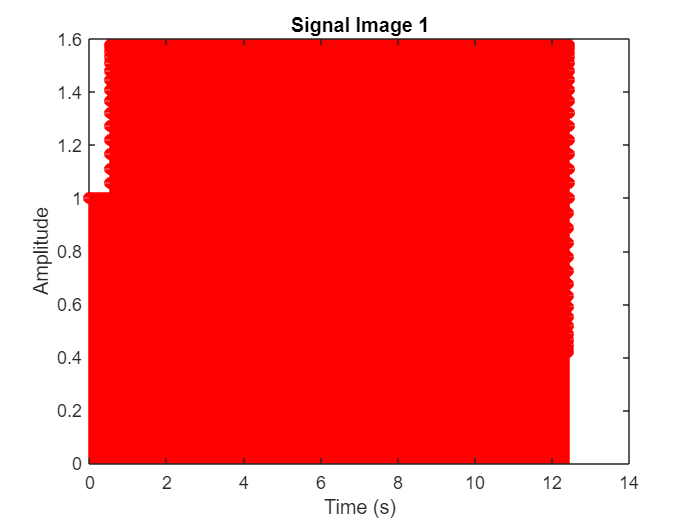

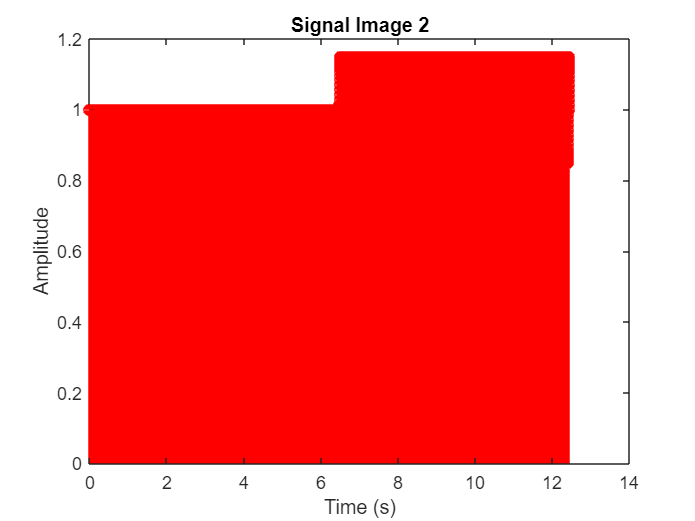

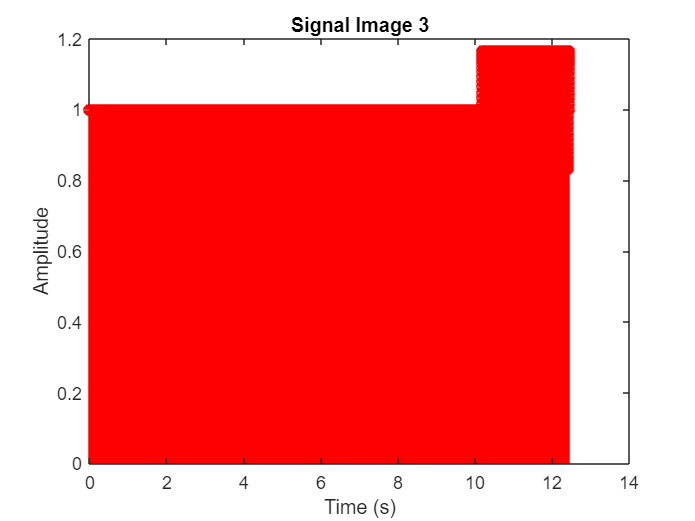

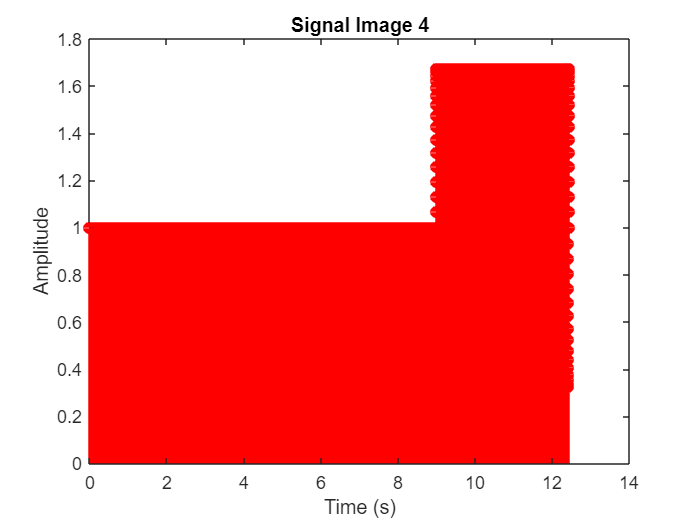

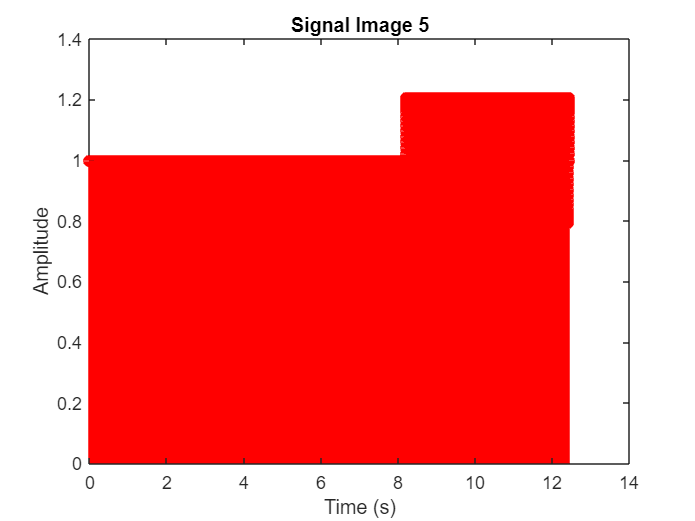

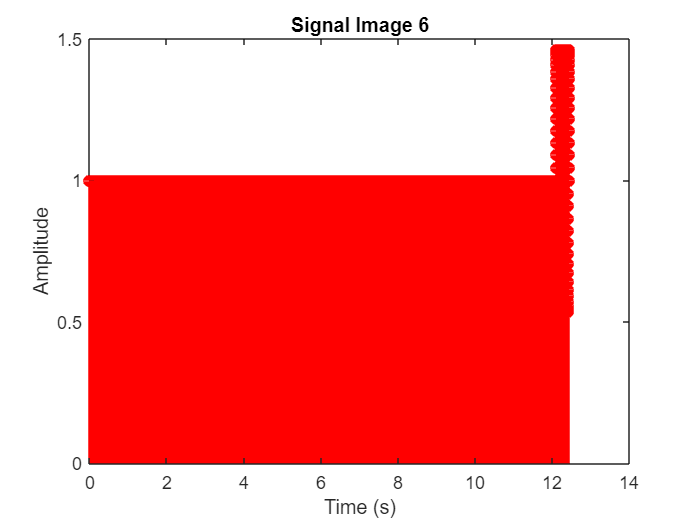

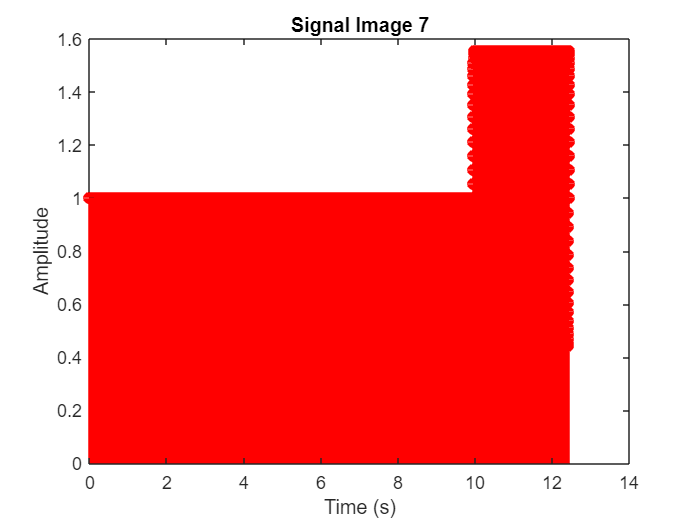

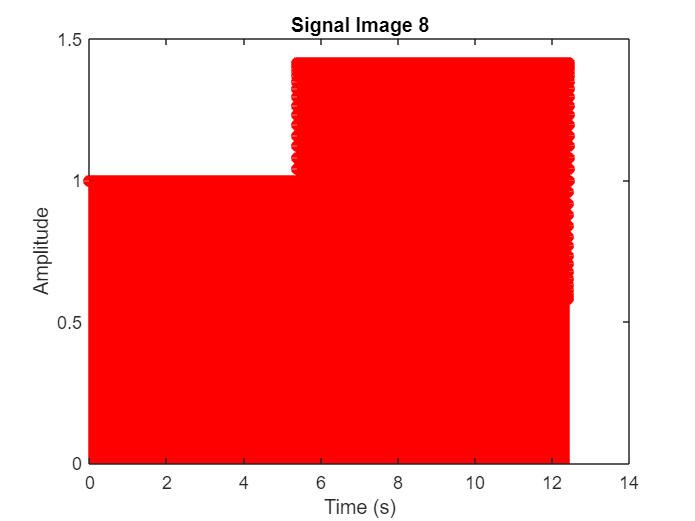

% Parameters
A = 1;                   % Amplitude
f = 50;                  % Frequency in Hz
sampling_rate = 3200;    % Sampling rate in Hz
num_cycles = 622;        % Number of cycles considered

% Time vector
T = 1 / f;                                      % Period of one cycle
duration = num_cycles * T;                      % Total duration of the signal
num_samples = duration * sampling_rate + 1;     % Number of samples
t = linspace(0, duration, num_samples);         % Time vector

% Angular frequency of the sinusoidal signal
omega = 2 * pi * f;
num_signals = 50;

% Generate 50 signal images
for signal_index = 1:num_signals
    % Define random parameters
    alpha = 0.1 + 0.7 * rand();   % Random alpha in [0.1, 0.8]
    t2 = duration * rand();       % Random t2 within the duration
    
    % Calculate the real part of the signal
    signal_real = (1 - alpha * (u(t - t2)) .* (sin(omega * t)));
    
    % Plot the real part of the signal as stem plot
    figure;
    stem(t, signal_real, 'r-');
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(['Signal Image ', num2str(signal_index)]);
end